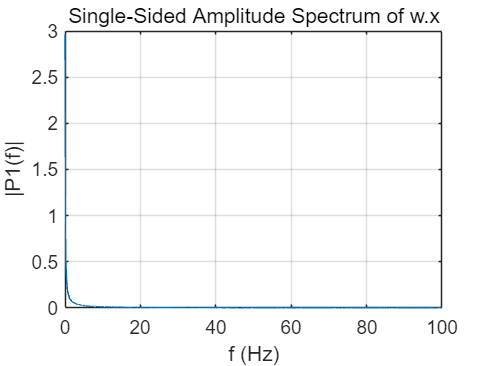

% 绘制三轴角速度信号的频谱
fs=200;
plot_spectrum(outw(:,1), fs, 'w.x');

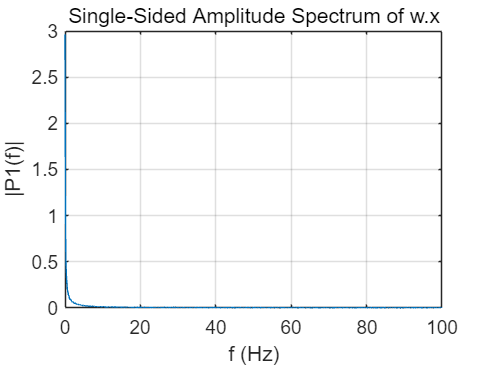

plot_spectrum(measure_w(:,1), fs, 'w.x');

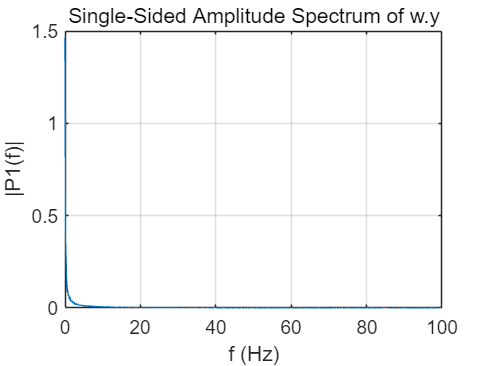

plot_spectrum(outw(:,2), fs, 'w.y');

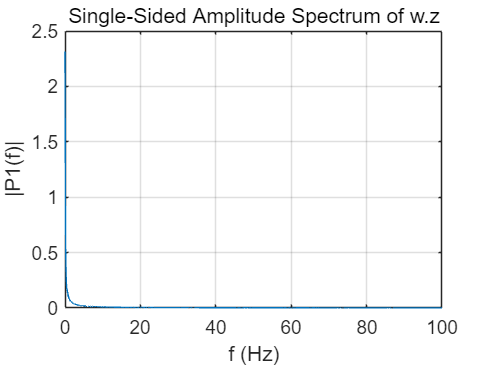

plot_spectrum(outw(:,3), fs, 'w.z');


% 定义一个函数来计算和绘制频谱

function plot_spectrum(data, fs, axis_label)
    L = length(data);  % 信号长度
    f = fs*(0:(L/2))/L;  % 频率向量

    % 计算 FFT
    Y = fft(data);
    P2 = abs(Y/L);  % 双边频谱
    P1 = P2(1:L/2+1);  % 单边频谱
    P1(2:end-1) = 2*P1(2:end-1);

    % 绘图
    figure;
    plot(f, P1);
    title(['Single-Sided Amplitude Spectrum of ', axis_label]);
    xlabel('f (Hz)');
    ylabel('|P1(f)|');
    grid on;
end

